# Timothy Jergens

Engineering Economics HW 2

Due: 08 February, 2019

**Problem 7.2**

The original cost for a distillation tower is $50,000, and the useful life of the tower is estimated to be 10 years. How much must be placed annually in an annuity at an interest rate of 6 percent to obtain sufficient funds to replace the tower at the end of 10 years? If the scrap value of the distillation tower is $5000, determine the asset value (i.e., the total book value of the tower) at the end of 5 years based on straight line depreciation.

%%% Given Values:
n = 10;                     % Useful life of tower (yrs)
OG = 50000;                 % Principal cost of distillation Tower ($)
F = 50000;
i = 0.06;                   % Interest per year (6%)
salvage = 5000;             % Salvage value of Tower ($)
n2 = 5;                     % Time in which to determine asset value (yrs)


%%% Calculations
% F = P(1+i)^n   -   rearranged 
P = F / ((1 + i)^n)

P = 2.7920e+04


% P = A((1 + i)^n - 1) / i * (1 + i)^n   -  rearranged
A = (P * i * ((1 + i)^n)) / (((1 + i)^n) - 1)

A = 3.7934e+03


% A is the value paid annually for ten years
Value = OG - salvage;                   % 50,000 - 5,000
depreciation = Value / n                % The amount that the tower depreciated

depreciation = 4500


Asset_Value = OG - depreciation * n2    % The value after five years 

Asset_Value = 27500

**There must be $3793/year placed annually **into an annuity over the span of 10 yrs.  

**The determined asset value is $27,500 **at the end of five years based on a straight line depreciation.

**Problem 7.5 (Use annualized cost)**

A heat exchanger is to be used in a heating process. A standard type of heat exchanger with a negligible scrap value costs $20,000 and will have a useful life of 6 years. Another type of heat exchanger with equivalent design capacity is priced at $34,000 but with a useful life of 10 years and a scrap value of $4000. Assume an effective compound interest rate of 6 percent per year and that the replacement cost of each exchanger is the same as that of the original exchanger. Determine which heat exchanger is cheaper by comparing the capitalized cost of each. See Prob. 7-4 for a definition of capitalized cost.

%%% Given Values:
n = 6;                     % Life of HE 1 is six years
P = 20000;                 % Principal cost of H/E 1 ($)

n2 = 10;                     % Life of HE 2 is ten years
P2 = 34000;                 % Principal cost of H/E 2 ($)
s = 4000;                   % Salvage value after ten years

i = 0.06;                   % Interest per year (6%)

%%% Calculations
A_P1 = P*(i*((i+1)^n))/(((1+i)^n)-1);

A_P2 = P2*(i*((i+1)^n2))/(((1+i)^n2)-1);
A_S2 = (4000 * i) / (((1+i)^n2)-1);

Total_Annualized_Cost_HE_1 = A_P1

Total_Annualized_Cost_HE_1 = 4.0673e+03


Total_Annualized_Cost_HE_2 = A_P2 - A_S2

Total_Annualized_Cost_HE_2 = 4.3160e+03

**The first heat exchanger is a better value as seen by comparing the annualized costs.**

The first heat exchanger costs $4,067.3 per year for the six years of operation.

The second heat exchanger costs $4,316.0 per year for the ten years of operation.

      - The second H/E cost was found by annualizing the initial investtement subteacted by the annualized salvage value.

**Problem 7.9**

The fixed-capital investment for an existing chemical plant is $20 million. Annual property taxes amount to 1 percent of the fixed-capital investment, and state income taxes are 5 percent of the gross earnings. The net income after all taxes is $2 million, and the federal income taxes amount to 35 percent of gross earnings. If the same plant had been constructed for the same fixed-capital investment but at a location where property taxes were 4 percent of the fixed- capital investment and state income taxes were 2 percent ofthe gross earnings, what would be the net income per year after taxes, assuming all other cost factors were unchanged?

%%% Given Values:
FC_I = 20000000;           % Fixed Capital Investment for existing Plant ($)
p_tax = 0.01 * FC_I;              % Property tax at 1 percent of Fixed Capital (%)
tax = 0.05;              % State income tax are 5% of gross earnings (%)
net_income = 2000000;      % Net income after all taxes = $2,000,000
f_tax = 0.35;              % Federalincome tax are 35% of gross earnings (%)

newp_tax = 0.04 * FC_I;           % Property tax at 1 percent of Fixed Capital (%)
newi_tax = 0.02;           % State income tax are 5% of gross earnings (%)

%%% Calculations
Gross_earnings = (net_income - p_tax) / (tax + f_tax);
New_Income = newp_tax + (newi_tax * Gross_earnings) + (f_tax * Gross_earnings)

New_Income = 2465000

**The new location will result in a net income of $2,465,000.**

**Problem 7.11**

The initial installed cost for a new piece of equipment is $10,000. After the equipment has been in use for 4 years, it is sold for $7000. The company that originally owned the equipment employs a straight-line method for determining depreciation costs. If the company had used the MACRS 5-year method for determining depreciation costs, the asset or book value for the piece of equipment at the end of 4 years would have been $1728. The total income tax rate for the company is 35 percent of all gross earnings. Capital gains taxes amount to 20 percent of the gain. How much net savings would the company have achieved by using the MACRS method instead of the straight-line depreciation method?

%%% Given Values:
n = 4;                     % Eq. sold at four years
P = 10000;                 % Installation cost of equipment ($)
salvage = 7000;            % Salvage value after 4 years ($)
book_v = 1728;             % Book value based on MACRS
tax = 0.35;              % Income tax rate is 35% of all gross earnings
cg_tax = 0.20;             % Tax of 20% of all capital gains


%%% Calculations


**Problem 7.14 - Hannah**

A chemical company has a total income of $1 million per year and total expenses of $600,000 not including depreciation. At the start of the first year of operation, a composite account of all depreciable assets shows a value of $850,000 with a MACRS recovery period of 5 years, and a straight-line recovery period of 9.5 years. Thirty-five percent of all profits before taxes must be paid out for income taxes. What would be the reduction in income tax charges for the first year of operation if the MACRS method were used for the depreciation accounting instead of the straight-line method?

%%% Given Values:
t_income = 1000000;         % total income of 1 million ($) per year
t_expenses = 600000;        % total expenses ($) per year



%%% Calculations



**Problem 7.17**

A laboratory piece of equipment was purchased for $35,000 and is estimated to be used for 5 years with a salvage value of $5000. Tabulate the annual depreciation allowances and year-end book values for the 5 years by using: (1) the straight-line depreciation method, (2) the MACRS 5-yr recovery period depreciation method, and (3) the sum-of-the-digits depreciation method.

%%% Given Values:
n = 5;                     % Life of equipment (yrs)
P = 35000;                 % Principal cost of laboratory equipment ($)
salvage = 5000;            % Sal;vage value after 5 years ($)
i = 0.06;                  % Interest per year (6%)

%%% Calculations
straightline_depreciation = (P - salvage) / n;

% MACRS
AN_DEP_YR_1 = 35000 * 0.2

AN_DEP_YR_1 = 7000

AN_DEP_YR_2 = 35000 * 0.32

AN_DEP_YR_2 = 11200

AN_DEP_YR_3 = 35000 * 0.192

AN_DEP_YR_3 = 6720

AN_DEP_YR_4 = 35000 * 0.1152

AN_DEP_YR_4 = 4032

AN_DEP_YR_5 = 35000 * 0.1152

AN_DEP_YR_5 = 4032

AN_DEP_YR_6 = 35000 * 0.0576

AN_DEP_YR_6 = 2016


% Sum of digits
Sum_Digits = n*(n+1)/2

Sum_Digits = 15

1) The straight-line depreciation Method

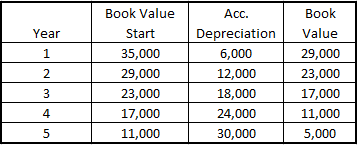

2) The MACRS 5-yr recovery period depreciation method

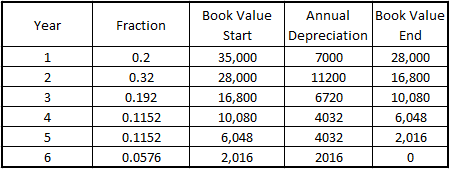

3) The sum-of-the-digits depreciation method

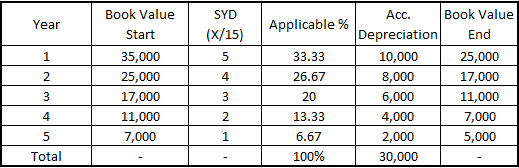

**Problem 8.4 (Use annualized Costs) **

Two pumps are being considered for pumping water from a reservoir. Installed cost and salvage value for the two pumps are given below:

Pump A has a service life of 4 years. Determine the service life of pump B at which the two pumps are competitive if the annual effective interest rate is 15 percent. Competitiveness refers to the requirement that the installed cost of the pumps plus the amount that must be invested at the time of installation so that sufficient interest will be earned over the service life (when added to the salvage value) to replace the pumps at the original cost.

%%% Given Values:
n_A = 4;                   % Life of pump A (yrs)
P_A = 20000;               % Principal cost of Pump A ($)
P_B = 25000;               % Principal cost of Pump B ($)
salvage_A = 2000;          % Salvage value for pump A after 4 (yrs)
salvage_B = 4000;          % Salvage value for pump B after X (yrs)
i = 0.15;                  % Interest per year (%)

n_B = 5.32;         % Life of pump B (yrs) TBD
                     % What is being calculated
                    
%%% Calculations
% Pump A
Annual_P_A = P_A*(i*((i+1)^n_A))/(((1+i)^n_A)-1);         % Annual Cost of Instillation
Annual_SalvageA = (salvage_A * i) / (((1+i)^n_A)-1);      % Annual Gain from Salvage
Total_Annualized_Cost_A = Annual_P_A - Annual_SalvageA;   % Annual Cost of Pump A

% Pump B
Annual_P_B = P_B*(i*((i+1)^n_B))/(((1+i)^n_B)-1);         % Annual Cost of Instillation
Annual_SalvageB = (salvage_B * i) / (((1+i)^n_B)-1);      % Annual Gain from Salvage
Total_Annualized_Cost_B = Annual_P_B - Annual_SalvageB;   % Annual Cost of Pump B

Since this problem was changed to annualized costs/salvage values, the problem statement chages slightly and the *Basic Time Value of Money Formulas *could be used. Since the lifespan of pump A was known, the annualized cost of instillation and annual salvage value could be calculated. 

The total annualized cost of Pump A per year is the annual instillation - annual salvage and was $6,604.8 

Since we know that the pumps should be competitive, the total annualized cost of Pump B should be the same $6,604.8. The same fourmuals were used for pump B, however, the n values (years of operation) was varied until the two annual costs were equal.

**When the annual cost of Pump B was also found to be $6,604, **

**the determined life span of Pump B was 5.32 years**

## **Problem 8.5 (Use annualized cost)**

A heat exchanger has been designed, and insulation is being considered for the unit. The insulation can be obtained in thicknesses of 0.025,0.051. 0.076, or 0.102 m. The following data have been determined for the differzent insulation thicknesses:

What thickness of insulation should be used? The value of heat is $1.50/GJ. An annual after-tax return of 15 percent on the fixed-capital investment is required for any capital utilized in this type of investment. The income tax rate is 35 percenl/yr. The exchanger operates for 300 days/yr.

%%% Given Values:
Thickness = [0.025, 0.051, 0.076, 1.02];             % (m)
kJs_saved = [88, 102, 108, 111];                     % KJ/s
Installed_cost = [8000, 10100, 11100, 11500];        % ($)
Annual_FC = 0.10;                                    % (%)

value_heat = 1.5;                                    % ($/GJ)
i = 0.15;                                          % (%)
tax = 0.35;                                        % (%)
op_days = 300;                                       % (operating days/yr)

%%% Calculations
Annual_FC = Annual_FC .* Installed_cost;            
           % Annual Fixed Cost is the the percentage times the installation cost
Savings_heat = kJs_saved .* (3600 * 24 * op_days) / 1000000;
           % The savings from the heat values
Savings_heatcost = Savings_heat * value_heat;
           % The savings from the heat cost
           
inc_tax = tax * Savings_heatcost;
           % The income tax is 35% times the heat cost savings
net_income = Savings_heatcost - inc_tax - Annual_FC;
Annual_return = i * Installed_cost;
           % How much money is returned for each thickness

Annual_profit = net_income - Annual_return

Annual_profit =   223.9360   52.7440  -45.6240  -69.8080


           % The annual profit for each thickness

Increase in Profit:

**0.025 m   -   $223.94**

0.051 m   -   $52.74

0.076 m   -   -$45.62

1.02 m     -   -$69.81

**The 0.025 m insulation size will be used because it returns the highest profit.**

**Problem 8.7 **

A company must purchase one reactor to be used in an overall operation. Four reactors have been designed, all of which are equally capable of giving the required service. The following data apply to the four designs:

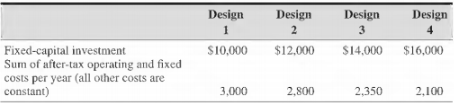

If the company demands a 15 percent return after taxes on any unnecessary investment, which of the four designs should be accepted?

%%% Given Values:
n = 6;                     % Life of HE 1 is six years
P = 20000;                 % Principal cost of H/E 1 ($)
i = 0.06;                   % Interest per year (6%)

%%% Calculations



**Problem 8.10 **

A proposed chemical plant has the following projected revenues and operating expenses in millions of dollars.

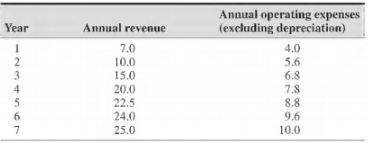

The fixed-capital investment for the plantis $50 million with a working capital of $7.5 million.Using a MACRS depreciation schedule with a class life of 5 years, determine:

a. The annual cash flows

b. The net present worth, using a nominal discount rate of 15 percent

c. The DCFR

%%% Given Values:
n = 6;                     % Life of HE 1 is six years
P = 20000;                 % Principal cost of H/E 1 ($)
i = 0.06;                   % Interest per year (6%)

%%% Calculations



**Problem 8.11**

A power plant for generating electricity is part of a plant design proposal. Two alternative power plants with the necessary capacity have been suggested. One uses a boiler and steam turbine while the other uses a gas turbine. The following information applies to the two proposals:

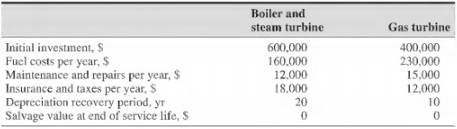

All other costs are the same for either type of power plant. A 12 percent return is required on any investment. If one of these power plants must be accepted, which one should be recommended?

%%% Given Values:
BS_P = 600000;
BS_salvage = 0;
BS_n = 20;
BS_Fuel = 160000;
BS_Maint = 12000;
BS_Insur = 18000;

Gas_P = 400000;
Gas_salvage = 0;
Gas_n = 10;
Gas_Fuel = 230000;
Gas_Maint = 15000;
Gas_Insur = 12000;

%Gas Turbine needs to be replaced to be considered on az 12% return
Gas_Pnew = Gas_P + (Gas_P/(1.12)^Gas_n)

Gas_Pnew = 5.2879e+05


%%% Calculations
BS_Deprec = (BS_P - BS_salvage) / BS_n

BS_Deprec = 30000

BS_expenditure = BS_Deprec + BS_Fuel + BS_Maint + BS_Insur

BS_expenditure = 220000



Gas_Deprec = (Gas_Pnew - Gas_salvage) / Gas_n

Gas_Deprec = 5.2879e+04

Gas_expenditure = Gas_Deprec + Gas_Fuel + Gas_Maint + Gas_Insur

Gas_expenditure = 3.0988e+05

Gas Turbine Expenditure = $309,878.90

Boiler and Steam Turbine Expenditure = $220,000

The boiler and steam turbine has a lower expenditure and a better percentage return than the Gas turbine.

## **Problem 8.13**

    A chemical company is considering replacing a batch reactor with a continuous reactor. The old unit cost $40,000 when new 5 years ago, and depreciation has been charged on a straight-line basis using an estimated service life of 10 years with a final salvage value of $1000. The new unit would cost $70,000. It would save $15,000 per year in expenses not including depreciation. The straight-line depreciation period is taken to be 10 years with a zero salvage value. All costs other than those for labor, insurance, taxes, and depreciation may be assumed to be the same for both units. The old unit can now be sold for $5000. Income tax is 35 percent per year. If the after-tax minimum acceptable return on any investment is 15 percent. Should the replacement be made?

***** Dr. Okos said to assume that the old, batch reactor was not five years into its life span as stated but was at zero but was already constructed. He said to asume this because he didn't want us to go into that depth of detail.**

%%% Givens
old_p = 40000;          % Principal of old bathc reactor [$]
old_salvage = 1000;     % Salvage value of old reactor [$]

new_p = 70000;          % Principal of old bathc reactor [$]
new_save = 15000;       % Save 15,000 in expenses [$]
old_sell = 5000;        % Salvage of old reactor [$]

tax = 0.35;             % Income tax = 35%
tax_back = 0.65;        % Get rest of 65% of money
i = 0.15;               % Investment return = 15%
n = 10;                 % Life of reactors (years)


%%% Calculations
batch_annual_cost = (old_p * i * ((1+i)^n)) /(((1+i)^n)-1);
batch_deprec = (4000 * tax);
batch_salvage = (old_salvage * i)/(((1+i)^n)-1);

new_annual_cost = ((new_p - old_sell) * i * ((1+i)^n)) /(((1+i)^n)-1);
new_deprec = ((new_p - old_sell)/n) * tax;
new_savings = (new_save * tax_back);

total_batch = batch_annual_cost - batch_deprec - batch_salvage

total_batch = 6.5208e+03

total_new = new_annual_cost - new_deprec + new_savings

total_new = 2.0426e+04

**The old, batch reactor is a better value as seen by comparing the two net cash flow values. **

The old, batch reactor costs costs $6521 per year in net cash flow

The new, continous reactor costs $20,426 per year in net cash flow

      - The old reactor's net cash flow was calculated by subtracting the depreciation and future salvage from the annual cost.

      - The new reactor's net cash flow was calculated by subtracting the depreciation and savings from the annual cost of buidling the new reactor.

**Problem 8.16 - Katie**

An engineer in charge ofthe design of a plant must choose either a batch or a continuous sys tem. The batch system offers a lower initial outlay but, because of higher labor requirements, exhibits a higher operating cost. The cash flows relevant to this decision have been estimated as follows:

Check the values given for the discounted cash flow rate ofreturn and net present worth. If the company requires a minimum rate of return of 10 percent, which system should be chosen?

%%% Given Values:
yr0_batch = -20000;               % ($)
yr10_batch = 5600;                % ($/yr)
int_batch = 0.25;                 % ($)
net_batch = 14400;                % ($)

yr0_cont = -30000;                % ($)
yr10_cont = 7650;                 % ($/yr)
init_cont = 0.22;                 % (%)
net_cont = 17000;                 % (%)

i = 0.10;                         % min rate of return (%)
n = 10;                           % Ten years run


%%% Calculations
Net_Pres_worth = yr0_batch;       % NPW = Net Present Worth
yrs = 1;                          % (years)
while yrs <= n
    Net_Pres_worth = Net_Pres_worth + (yr10_batch / ((1 + i) ^ yrs));
    yrs = yrs + 1;
end
Net_Pres_worth

Net_Pres_worth = 1.4410e+04


yrs = 1;
Net_Pres_cont = yr0_cont;
while yrs <= n
    Net_Pres_cont = Net_Pres_cont + (yr10_cont / ((1 + i) ^ yrs));
    yrs = yrs + 1;
end
Net_Pres_cont

Net_Pres_cont = 1.7006e+04


Net_Pres_worth = yr0_batch;
yrs = 1;
while yrs <= n
    Net_Pres_worth = Net_Pres_worth + (yr10_batch / ((1 + int_batch) ^ yrs));
    yrs = yrs + 1;
end
Net_Pres_worth

Net_Pres_worth = -5.1817


yrs = 1;
Net_Pres_cont = yr0_cont;
while yrs <= n
    Net_Pres_cont = Net_Pres_cont + (yr10_cont / ((1 + int_batch) ^ yrs));
    yrs = yrs + 1;
end
Net_Pres_cont

Net_Pres_cont = -2.6856e+03

The net present values are the correct values while the IRR values are not.. 

**The continous reactor has a higher Net Present Worth and should be chosen.**

**Problem 8.17 - Barb**

An oil company is offered a lease of a group of oil wells on which the primary reserves are close to exhaustion. The major condition of the purchase is that the oil company agree to undertake a water flood project at the end of 5 years to undertake possible secondary recovery. No immediate payment by the oil company is required. The relevant cash flows have been estimated as follows:

Continuous, constant cash flows were used except for the expenditure that occurs in one sum at the end of year 5. Continuous discounting at 10 percent per year was used for all cash flows. Check the net present worth value. Should the lease and flood arrangement be accepted? How should this proposal be presented to the company board of directors who understand and make it a policy to evaluate proposals by using the discounted cash flow rate of return method?

%%% Given Values:
n = 6;                     % Life of HE 1 is six years
P = 20000;                 % Principal cost of H/E 1 ($)
i = 0.06;                   % Interest per year (6%)

%%% Calculations




**Problem 8.18 - Hannah**

A process with a depreciable capital investment of $100 million is to be constructed over a 3-year period. At start-up, $20 million of working capital is required. The plant is expected to operate for 10 years. At full capacity expected for the third and subsequent years of operation, the sales revenues are projected to be $150 million per year, and the total operating expenses, excluding depreciation, are projected to be $100 million per year. During the first and second years of operation, the sales revenues are anticipated to be 50 and 75 percent of the sales revenues projected in the third and subsequent years, respectively. The operating expenses during the first and second years will be the same as in the third and subsequent years. Assume that the income tax rate is 35 percent. Using the third year as a basis, determine:

a. The return on the investment after taxes

b. The payback period

%%% Given Values:
n = 6;                     % Life of HE 1 is six years
P = 20000;                 % Principal cost of H/E 1 ($)
i = 0.06;                   % Interest per year (6%)

%%% Calculations

